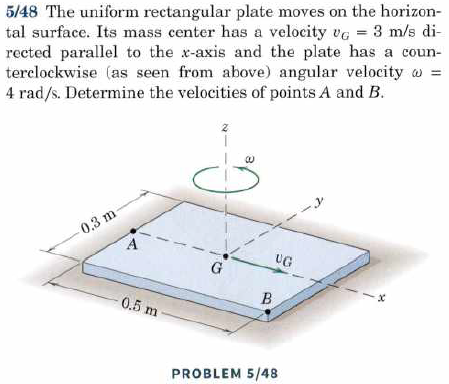

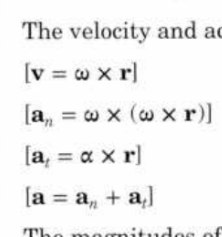

omega = 4

omega = 4

v_G = [3; 0; 0]

v_G =      3
     0
     0



r_A = [-0.25; 0; 0]

r_A =    -0.2500
         0
         0


omega_A = [0; 0; 4]

omega_A =      0
     0
     4


v_A = cross(omega_A, r_A) + v_G

v_A =      3
    -1
     0


v_A_tot = norm(v_A)

v_A_tot = 3.1623


r_B = [0.25; -0.15; 0]

r_B =     0.2500
   -0.1500
         0


omega_B = [0; 0; 4]

omega_B =      0
     0
     4


v_B = cross(omega_B, r_B) + v_G

v_B =     3.6000
    1.0000
         0


v_B_tot = norm(v_B)

v_B_tot = 3.7363

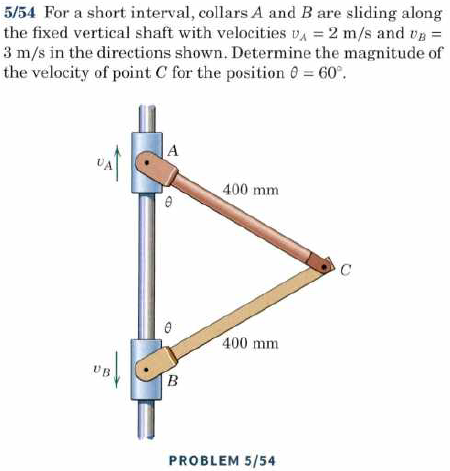

clear all
v_A = [0; 2; 0]

v_A =      0
     2
     0


v_B = [0; -3; 0]

v_B =      0
    -3
     0



AC = 0.4;
BC = 0.4;

theta = deg2rad(60);

% r_AC = [-AC / tan(theta); AC * tan(theta); 0]
% 
% r_BC = [-BC / tan(theta); -BC * tan(theta); 0]

r_AC = [-AC * sin(theta); AC * cos(theta); 0]

r_AC =    -0.3464
    0.2000
         0



r_BC = [-BC * sin(theta); -BC * cos(theta); 0]

r_BC =    -0.3464
   -0.2000
         0



omega_AC = cross(v_A, r_AC) 

omega_AC =          0
         0
    0.6928



omega_BC = cross(v_B, r_BC) 

omega_BC =          0
         0
   -1.0392



omega_C = omega_AC + omega_BC

omega_C =          0
         0
   -0.3464



r_C = r_AC + r_BC

r_C =    -0.6928
         0
         0



v_C = cross(omega_C, r_AC)

v_C =     0.0693
    0.1200
         0




% v_AC = [2 / tan(theta); 2 * tan(theta); 0] %+ v_A
% 
% v_BC = [-3 / tan(theta); -3 * tan(theta); 0] %+ v_B

% v_C = v_AC + v_BC

norm(v_C)

ans = 0.1386


% v_CB = v_BC - v_B
% norm(v_CB)
% 
% v_C = v_CA - v_CB
% norm(v_C)